1.

int = integral(@(x) f(x),1,2)

int = 0.6363

2.

h = 1;
trap = h/2 * (f(1)+f(2))

trap = 0.6931


h=1/2;
simp = h/3 * (f(1)+4*f(1.5)+f(2))

simp = 0.6365

4

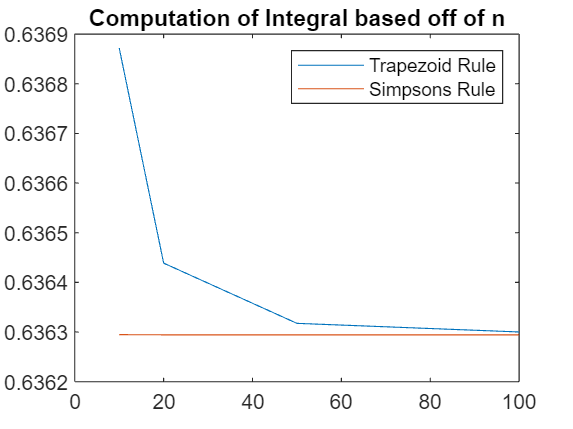

a = 1;
b=2;
n=[10,20,50,100];
trap10 = composite_trapezoid(a,b,10);
trap20 = composite_trapezoid(a,b,20);
trap50 = composite_trapezoid(a,b,50);
trap100 = composite_trapezoid(a,b,100);
simp10 = composite_simpsons(a,b,10);
simp20 = composite_simpsons(a,b,20);
simp50 = composite_simpsons(a,b,50);
simp100 = composite_simpsons(a,b,100);
plot(n,[trap10,trap20,trap50,trap100],n,[simp10,simp20,simp50,simp100])
legend('Trapezoid Rule', 'Simpsons Rule')
title('Computation of Integral based off of n')

Functions

function y = f(x)
    y = x.* log(x);
end

function [trap] = composite_trapezoid(a,b,n)
    h = (b-a)/n;
    x = a:h:b;
    F = f(x);
    trap = sum(h/2*(F(1:end-1)+F(2:end)));
end

function [simp] = composite_simpsons(a,b,n)
    h = (b-a)/n;
    x = a:h:b;
    F = f(x);
    simp = sum(h/3*(F(1:2:end-2)+4*F(2:2:end-1)+F(3:2:end)));
end

